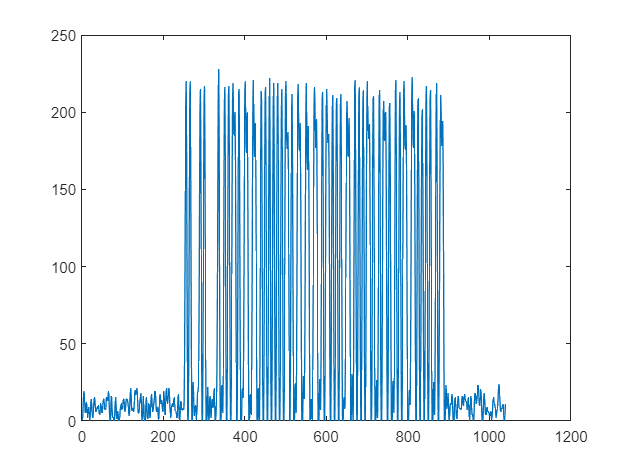

%Irasyti sugeneruota signala i txt faila generavimui
clear
data_binary = [1 0 0 0 1 1 0 1 0 1 0 0 0 0 0 0 0 1 1 0 1 0 1 0 1 0 0 1 1 1 1 0]';
packet_bits = GenerateBits(data_binary);
signal_strength = 1;
[idealSignal1, noisySignal1, discretizedSignal1, ADCsignal1, ADCpreambule1] = GenerateSignal(packet_bits, signal_strength);
%10001101 01000000 01101010 10011110 10000110 01100010 11111001 8D406A9E8662F9

plot(ADCsignal1)

current_directory = pwd;

%Txt for signal generator and vhdl simulation
full_path = fullfile(current_directory, 'test_signals_generated/testVoltage.txt');
testVoltage = fopen(full_path,'w');

for i = 1: length(ADCsignal1)
    fprintf(testVoltage,'%d\n',ADCsignal1(i));
end
fclose(testVoltage);

save("test_signals_generated\TestVoltage.mat", "ADCpreambule1", "ADCsignal1", "discretizedSignal1", "idealSignal1", "noisySignal1")